# Task 3.2

clc;
clear;
close all;

## Load and plot data

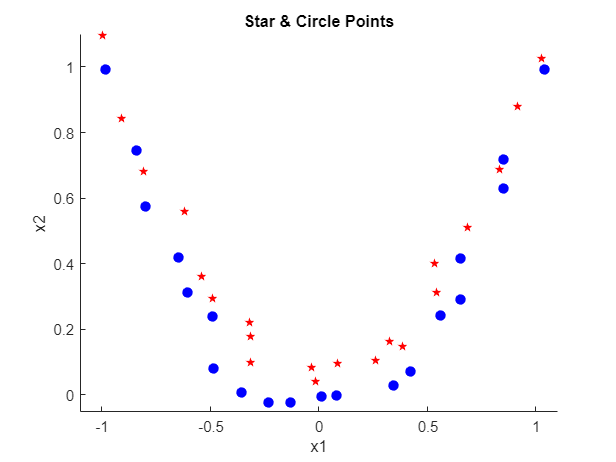

data = load("data32.mat");
stars = data.stars; % Get star points
circles = data.circles; % Get circle points
%===========PLOT==========%
scatter(stars(:,1), stars(:,2), 50, 'rp', 'filled')
hold on;
scatter(circles(:,1), circles(:,2), 50, 'blue', 'filled')
title('Star & Circle Points')
xlabel('x1')
ylabel('x2')
xlim([-1.1 1.15])
ylim([-0.1 1.15])

## Calculate Errors

%================%


For h = 0.001


Calculating error for l = 0


Total error: 0%


n = 40000

Calculating error for l = 0.1


Total error: 0%


n = 40000

Calculating error for l = 1


Total error: 0%


n = 40000

Calculating error for l = 5


Total error: 0%


n = 40000

Calculating error for l = 10


Total error: 0%


n = 40000

%================%


For h = 0.01


Calculating error for l = 0


Total error: 0%


n = 40000

Calculating error for l = 0.1


Total error: 0%


n = 40000

Calculating error for l = 1


Total error: 2.381%


n = 40000

Calculating error for l = 5


Total error: 2.381%


n = 40000

Calculating error for l = 10


Total error: 2.381%


n = 40000

%================%


For h = 0.1


Calculating error for l = 0


Total error: 0%


n = 40000

Calculating error for l = 0.1


Total error: 4.7619%


n = 40000

Calculating error for l = 1


Total error: 14.2857%


n = 40000

Calculating error for l = 5


Total error: 19.0476%


n = 40000

Calculating error for l = 10


Total error: 28.5714%


n = 40000

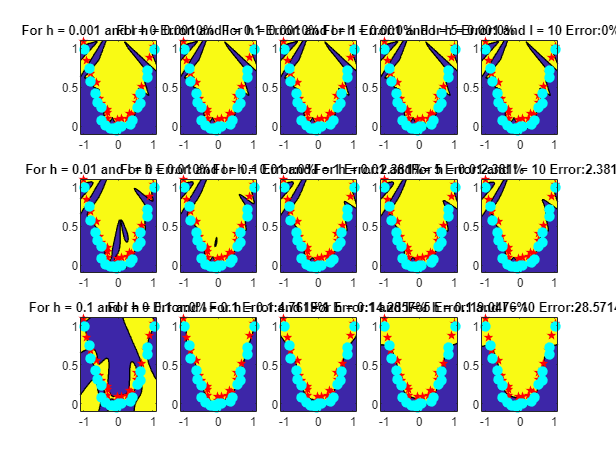

h = [0.001 0.01 0.1]; % Set h values
l = [0 0.1 1 5 10]; % Set l values

stars_n = size(stars, 1); % Stars amount
circles_n = size(circles,1); % Circles amount

star_labels = ones([1, stars_n]); % Label Stars as 1
circle_labels = -ones([1, circles_n]); % Label Circles as -1

X = [stars; circles]; % Stack stars and cricles
Y = [star_labels circle_labels]'; % Stack the labels

X = reshape(X' , [1, 2, stars_n+circles_n]) - X; % Calculate the value for the Kernel

plot_cnt = 1;
for i=1:size(h,2)
    disp('%================%')
    disp(['For h = ' num2str(h(i))])

    for j=1:size(l,2)
        disp(['Calculating error for l = ' num2str(l(j))])
        
        % Calculate parameter vector
        C = (inv(K(X, h(i), stars_n+circles_n) + l(j) * eye(stars_n + circles_n))) * Y;

        a = C(1:stars_n)'; % Take the first 21 parametes that are for the stars
        b = C(circles_n+1:end)'; % Take the last 21 parameters that are for the circels
        
        star_error = calculateError(stars, stars, circles, a, b, h(i));
        star_error = star_error(2); % Calcualte the star error

        circle_error = calculateError(circles, stars, circles, a, b, h(i));
        circle_error = circle_error(1); % Calculate the circle error
        
        total_error = (star_error + circle_error)/(stars_n +circles_n); % Calculate total error    
        disp(['Total error: ' num2str(total_error*100) '%'])
        
        lin_x = linspace(-1.1, 1.15, 200);
        lin_y = linspace(-0.1, 1.15, 200);
        [x_mesh, y_mesh] = meshgrid(lin_x, lin_y);

        x = reshape(x_mesh', [size(x_mesh,1)^2, 1]);
        y = reshape(y_mesh', [size(y_mesh,1)^2, 1]);

        x = [x y];                
        n = size(x,1)

        X_a = reshape(x', [1,2,n]) - stars;
        X_b = reshape(x', [1,2,n]) - circles;

        t = sum(a * K(X_a, h(i), n), 1) +  sum(b * K(X_b, h(i), n), 1);
        
        srf = reshape(t,[length(lin_x),length(lin_y)])';
        srf(srf>0) = 1;
        srf(srf<0) =-1;

        subplot(size(h,2), size(l,2), plot_cnt)
        contourf(x_mesh,y_mesh,srf);
        hold on;
        scatter(stars(:,1), stars(:,2), 50, 'rp', 'filled')
        hold on;
        scatter(circles(:,1), circles(:,2), 50, 'cyan', 'filled')
        title(['For h = ' num2str(h(i)) ' and l = ' num2str(l(j)) ' Error:' num2str(total_error*100) '%']);        
        plot_cnt = plot_cnt + 1;
    end
end

## Functions

function prob_dens = K(x, h , n) % Kernel
    nrm = vecnorm(x,2,2);
    prob_dens  = exp((-1/h)*(reshape(nrm,[size(x,1),n]).^2));
end

function error = calculateError(x, stars, circles, a, b, h)
    error = [0 0];
    n = size(x,1);

    X_a = reshape(x', [1,2,n]) - stars;
    X_b = reshape(x', [1,2,n]) - circles;
    
    t = sum(a * K(X_a, h, n), 1) +  sum(b * K(X_b, h, n),1);

    error(1) = nnz(t>0);
    error(2) = nnz(t<0);
end